# Optyczny system pomiaru tętna

Jednym ze sposobów pomiaru tętna jest czujnik optyczny badający zmianę natężenia światła przechodzącego przez tkanki w momencie przepływu krwi (w rytmie zgodnym z biciem serca). Zadanie polega na zarejestrowaniu a następnie przeanalizowaniu tego typu nagrania w celu wyznaczenia tętna.

## Rejestracja sygnału wejściowego

Jako czujnik w tym ćwiczeniu wykorzystana zostanie kamera w telefonie komórkowym. Proszę ustawić ją w tryb nagrywania wideo, rozdzielczość może być ustawiona najniższa dostępna (np. VGA - 640x480). Proszę docisnąć palec wskazujący do obiektywu i poczekać, aż automatyka aparatu zwiększy czułość do takiego poziomu, że na ekranie będzie widać różowo-czerwoną plamę. Nagranie najlepiej wykonywać w ciągu dnia przy mocnym oświetleni słonecznym, ewentualnie można włączyć w telefonie diodę obok aparatu. Po ustabilizowaniu się jasności na ekranie proszę rozpocząć nagranie i nagrać co najmniej 10-cio sekundowe wideo. W tym czasie proszę trzymać palec na obiektywie możliwie stabilnie, bez zmiany nacisku i jego przesuwania. Przykładowe nagranie zamieszczone jest poniżej (można je też [pobrać](https://leon.pw.edu.pl/pluginfile.php/123695/mod_assign/intro/output.mp4.zip)). Na nagraniu widać bardzo delikatną zmianę jasności obrazu - jej częstotliwość należy zmierzyć.

## Przygotowanie danych do analizy

Najłatwiejszą metodą załadowania danych do Matlaba jest przerobienie nagrania na serię obrazów a następnie ich wczytanie (ładowanie filmów często wymaga dodatkowych kodeków). W celu przerobienia nagrania na serię osobnych klatek można wykorzystać program `ffmpeg`:

`ffmpeg -r 1 -i movie.mp4 -r 1 frame_``%03d.jpg`

Następnie można wczytać ramki i dla każdej z nich wyznaczyć średnią jasność obrazu (będzie to podstawa wszelkich dalszych obliczeń):

% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 600;

% wektor jasności
br = zeros(3, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    v = VideoReader(['data/IMG_5844.mp4']);
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    h = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(h/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);

Po wyznaczeniu jasności można wyświetlić jej wykres - widać na nim wyraźnie cykliczne zmiany, które odpowiadają pulsowi. Dla pojedynczego punktu widać bardzo wyraźnie kwantyzację danych (skokowe zmiany wartości), wykreś wartości średniej jest dużo gładszy.

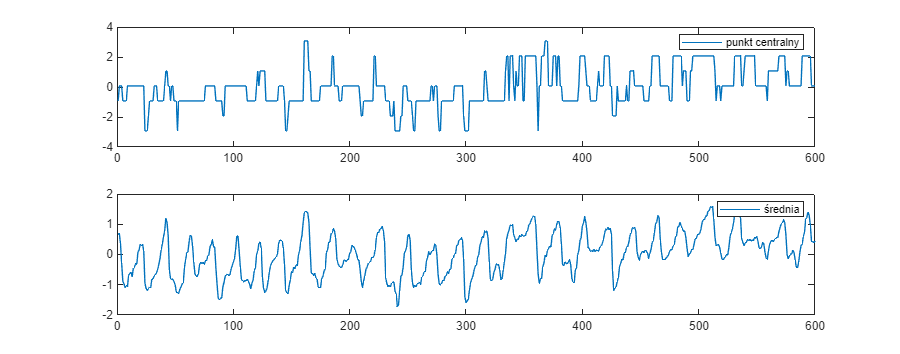

h = figure();
set(h,'Units','normalized','Position',[0 0 1 .7]); 
subplot(2,1,1);
plot(br(1,:));
legend('punkt centralny')
subplot(2,1,2);
plot(br(2,:));
legend('średnia');

## Zadanie

Proszę wyznaczyć wartość tętna (mierzoną w uderzeniach na minutę - BPM) na zarejestrowanym nagraniu. W tym zadaniu proszę zastosować metodę korzystającą bezpośrednio z zarejestrowanych danych w dziedzinie czasu (np. zliczanie przejść przez zero bądź detekcję lokalnych ekstremów). 

Proszę określić, z jaką rozdzielczością możliwe jest wyznaczenie tętna oraz ewentualne metody na jej poprawę.

Jako rozwiązanie proszę przesłać raport (pdf) zawierający:

- opis rozwiązania

- wykres przedstawiający zarejestrowane tętno

- otrzymane wyniki

- analizę rozdzielczości pomiaru

- kod funkcji dokonującej obliczenia

[peaks, locs] = findpeaks(br(2, :), "MinPeakProminence", 0.5)

peaks =     0.3446    1.2042    0.6479    0.4894    0.6173    0.4137    0.4757    1.4154    0.8628    0.2989    0.9351    0.6697    0.3389    0.5628    0.7731   -0.3071    1.0054    1.2683    1.1179    1.2500    0.8991    0.8908    1.2886    1.0609    1.5786    1.5291    1.1441    1.4163


locs =     20    42    63    82   104   123   140   162   186   202   228   251   273   296   318   326   340   359   379   402   422   445   465   484   512   534   573   594


### Wykres tętna z zaznaczonymi ekstremami

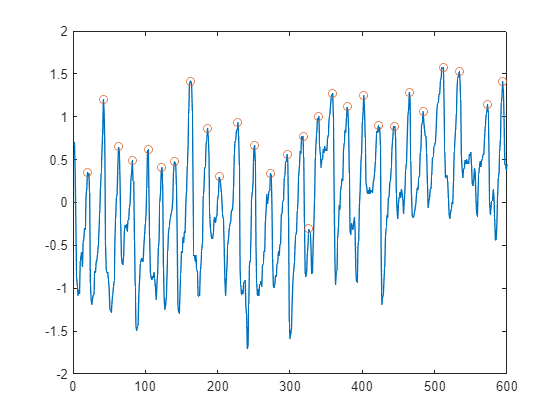

figure;
plot(br(2,:));

hold on;
scatter(locs, peaks);

### Obliczenia

FPS = 30;
peak_first = locs(1);
peak_last = locs(end);
measured_length = (peak_last - peak_first) / FPS / 60;
beats = length(peaks);



BPM = (beats - 1)/ measured_length;

### Wynik pomiaru

disp(BPM);

   84.6690



### Opis rozwiązania

Aby zmierzyć tętno, pzreanalizowano zmianę w poziomach jeasności nagrania z dociśniętej do palca kamery telefonu z włączonym naświetleniem. Film nagrano w 30 klatkach na sekundę oraz wymiarach obrazu 1920x1080px. Z każdej klatki wyciągnięto jedynie czerwony kanał, oraz wyznaczono średnią wartość wszystkich pikseli z obrazu. Po odjęciu wartości stałej z całego pomiaru otrzymano przybliżony przebieg tętna. Wykorzystując wbudowaną funkcję findpeaks znaleziono wszystkie znaczące ekstrema globalne sygnału. Przebieg sygnału z zaznaczonymi znalezionymi ekstremami przedstawiono na wykresie. 

Wyznaczono odległość między pierwszą i ostatnią próbką i mierząc czas między w minutach wykorzystując fakt, że film nagrywano w 30FPS. Na podstawie tych obliczeń wyznaczono średni okres między uderzeniami dając pomiar tętna. 

### Analiza rozdzielczości pomiaru

???